# PW4 – COMPUTATIONAL METHODS

## Optimization for Control

## Control tuning

The objective of this study is to establish a method for parameters tuning of a controller intended to improve the performance of a process whose transfer function is of the 3-order G(s) =${1/\left(1+s\right)}^2$.

The controller is a PID controller written as 2 C(s) = (a + bs + c$s^2$ )/ s whose parameters vector is $\theta$=${\left(\textrm{abc}\right)}^T$ .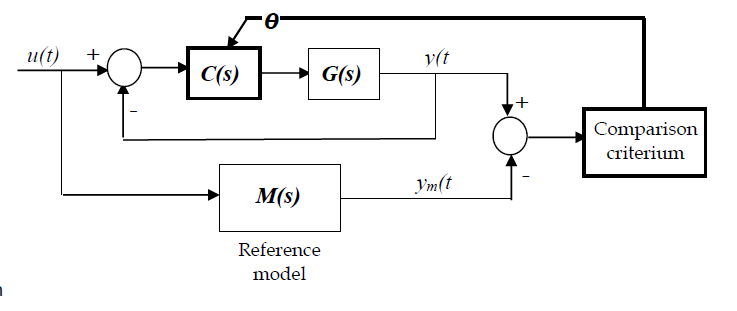

### PART I – Model formulation and performance study

1 - Simulation of a reference input

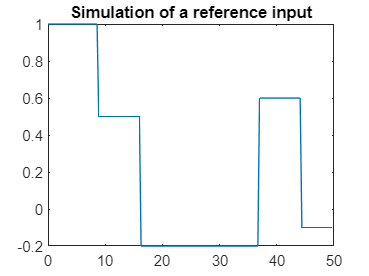

x1 = ones(1,30);
x2(1:1,1:25) = 0.5;
x3(1:1,1:35) = -0.2;
x4(1:1,1:35) = -0.2;
x5(1:1,1:25) = 0.6;
x6(1:1,1:19) = -0.1;
u = [x1 x2 x3 x4 x5 x6];
total_time=50; % Explaination
tt=0:total_time/(size(u,2)):total_time-0.00001; %Starting time, steps and finishing time.
plot(tt,u)
title("Simulation of a reference input")

2 – Non-Controlled system study

numerator = 1;
denominator = [1 3 3 1];
G = tf(numerator,denominator)

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



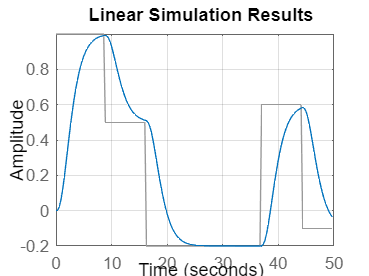

lsim(G,u,tt)
grid on

Here, the response time can be seen around 10 and no overshoot has been noted. Moreover, it is not precise or accurate.

#### 3 – Reference model conception

3.1- Calculate the coefficients $\xi$ and $\omega_n$ of reference model M(s) .

$\xi$ = 0.6362

$\omega_n$ = 2.715

3.2- Simulate the response ym(t) of this model thanks to the reference input. Represent on the same graph input u(t) and output ym(t) and then y(t) and ym(t).

numerator = 7.371225;
denominator = [1 3.4545 7.371225];
M = tf(numerator,denominator)

M =
 
          7.371
  ---------------------
  s^2 + 3.454 s + 7.371
 
Continuous-time transfer function.



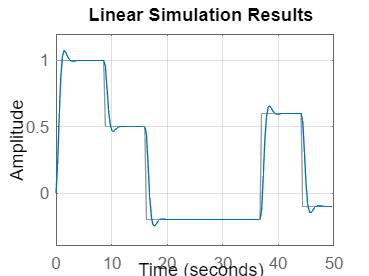

lsim(M,u,tt)
grid on

3.3- Does the model seem to have any good performances ?

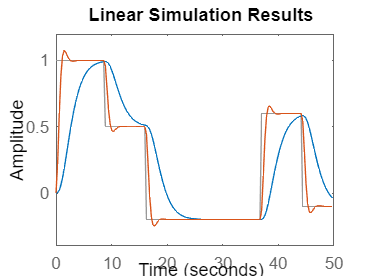


lsim(G,u,tt)
hold on

lsim(M,u,tt)
hold off

At the start, we can observed some flactuation for ym but still it is more accurate and precise.

### PART II – Controller optimal tuning

#### 1 – System sensitivity

1.1- Show that these sensitivities are solution of linear differential equations.

syms a b c s t
Y = (a+b*s+c*s^2)/(a+(b+1)*s+(c+3)*s^2+3*s^3+s^4);
y=ilaplace(Y,s,t);
a_diff = diff(y,a);
b_diff = diff(y,b);
c_diff = diff(y,c);

1.2- Write the transfer functions de transfert defining these sensitivities.


a_lap = laplace(a_diff);
b_lap = laplace(b_diff);
c_lap = laplace(c_diff);

#### 2 – Controller parameters tuning : Gradient method

2.1- Write a MATLAB code for this algorithm


Y_m = 7.371 /(s^2 + 3.454*s + 7.371);
y_m=ilaplace(Y_m,s,t);
a0 = 1;
b0 = 1;
c0 = 1;
alpha = 0.5;

for n = 1:4
y_t = subs(y,{a,b,c},{a0,b0,c0});
a_diff = subs(a_diff,{a,b,c},{a0,b0,c0});
b_diff = subs(b_diff,{a,b,c},{a0,b0,c0});
c_diff = subs(c_diff,{a,b,c},{a0,b0,c0});

fi_diff_1 = matlabFunction(vpa((y_t-y_m)*a_diff));
fi_diff_2 = matlabFunction(vpa((y_t-y_m)*b_diff));
fi_diff_3 = matlabFunction(vpa((y_t-y_m)*c_diff));

grad_a = integral(fi_diff_1,0, Inf);
grad_b = integral(fi_diff_2,0, Inf);
grad_c = integral(fi_diff_3,0, Inf);


a0 = a0 - alpha*grad_a;
b0 = b0 - alpha*grad_b;
c0 = c0 - alpha*grad_c;
end


2.2- On the same graph, compare respectively input u(t) and output ym(t), input u(t) output y(t),

outputs y(t) and ym(t).

sys3 = tf([c0 b0 a0], [1 3 c0+3 b0+1 a0])

sys3 =
 
         1.441 s^2 + 1.149 s + 0.6917
  ------------------------------------------
  s^4 + 3 s^3 + 4.441 s^2 + 2.149 s + 0.6917
 
Continuous-time transfer function.



t=1:169;
lsim(M,u,t);

hold on;
lsim(sys3,u,t);

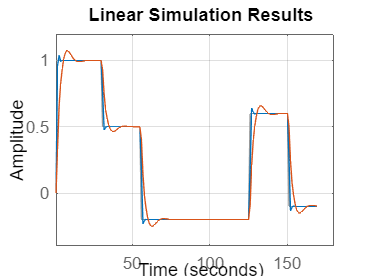

hold off;
grid on;

In the beginning the poor result can be noticed for y(t). But with increase of the iteration, better result can be noticed and in case of changing the step size, poor result will be noticed.